clear; clc; close all;

fs = 1000;          
tmax = 3;          
dt = 1/fs;          
t = 0:dt:(tmax - dt);
N = length(t);       

flow  = 50;          
fmid  = 200;         
fhigh = 300;         

signal_low  = sin(2*pi*flow*t);
signal_mid  = sin(2*pi*fmid*t);
signal_high = sin(2*pi*fhigh*t);
composite_signal = signal_low + signal_mid + signal_high;
X     = fft(composite_signal);
X_mag = abs(X) / N;      
f     = (0:N-1) * (fs/N);
halfN = floor(N/2) + 1; 
X_mag_single = X_mag(1:halfN);
f_single     = f(1:halfN);

if mod(N, 2) == 0
    X_mag_single(2:end-1) = 2 * X_mag_single(2:end-1);
else
    X_mag_single(2:end) = 2 * X_mag_single(2:end);
end
samples_to_plot = 1:50;  

figure('Name','Composite Signal & Single-Sided FFT','NumberTitle','off');
subplot(2,1,1);
plot(t(samples_to_plot), composite_signal(samples_to_plot), 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Composite Signal (First 50 ms)');

subplot(2,1,2);
stem(f_single, X_mag_single, 'filled');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Amplitude Spectrum');
xlim([0 500]); 

%task 2
clc; clear; close all;
fs = 1000;           
tmax = 3;             
dt = 1/fs;            
t = dt:dt:tmax;      
N = length(t);       

fc = 100;            
Omega_p2 = 2*pi*fc/fs;
Omega_s2 = 1.1 * Omega_p2;
Omega_t2 = Omega_s2 - Omega_p2;
Omega_c = (Omega_p2 + Omega_s2) / 2; 

f_low = 50;         
f_mid = 200;          
f_high = 400;         

signal_low = sin(2*pi*f_low*t);
signal_mid = sin(2*pi*f_mid*t);
signal_high = sin(2*pi*f_high*t);
xt = signal_low + signal_mid + signal_high;

Xs = fft(xt, N);
X = fftshift(Xs) / N;
freq = linspace(-fs/2, fs/2, N);

figure;
subplot(3,1,1);
plot(freq, abs(X), 'linewidth', 2);
ylim([0 1.2]);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');

L = 51;                   
M = (L-1)/2;              
n = 0:(L-1);           

h_ideal = sin(Omega_c*(n - M)) ./ (pi*(n - M));
h_ideal(M+1) = Omega_c / pi; 

%hanning: a = 0.5, b = 0.5, c = 0 so W[n] = 0.5 - 0.5*cos(2*pi*n/(L-1))
w = 0.5 - 0.5*cos(2*pi*n/(L-1));

h = h_ideal .* w;        
H = fft(h, N);
H = fftshift(H);
H_mag = abs(H);

subplot(3,1,2);
plot(freq, H_mag, 'linewidth', 2);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Spectrum of Low-Pass Filter');
xlim([-fs/2 fs/2]);

y = conv(xt, h, 'same');
Ys = fft(y, N);
Y = fftshift(Ys) / N;

subplot(3,1,3);
plot(freq, abs(Y), 'linewidth', 2);
ylim([0 1.2]);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');


%task 3
clc; clear; close all;

fs   = 1000;     
tmax = 3;         
dt   = 1/fs;      
t    = 0:dt:(tmax-dt); 
N    = length(t);  

f_low  = 50;     
f_mid  = 200;      
f_high = 400;      
x_low  = sin(2*pi*f_low*t);
x_mid  = sin(2*pi*f_mid*t);
x_high = sin(2*pi*f_high*t);

xt = x_low + x_mid + x_high;

Xs   = fft(xt, N);
X    = fftshift(Xs) / N;
freq = linspace(-fs/2, fs/2, N);

figure('Name','High-Pass Filter (Task 3)','NumberTitle','off');
subplot(3,1,1);
plot(freq, abs(X), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');

fc = 150;          
L  = 51;             
M  = (L - 1) / 2;   
n  = 0:(L-1);

omega_c = 2*pi*fc/fs;
h_ideal_lp = sin(omega_c * (n - M)) ./ (pi * (n - M));
h_ideal_lp(M+1) = omega_c / pi;
ap = sin(pi * (n - M)) ./ (pi * (n - M));
ap(M+1) = 1;
h_ideal_hp = ap - h_ideal_lp;
% Hanning formula: w[n] = 0.5 - 0.5*cos(2*pi*n/(L-1))
w = 0.5 - 0.5*cos(2*pi*n/(L-1));
h_hp = h_ideal_hp .* w;

y = conv(xt, h_hp, 'same');

H = fftshift(fft(h_hp, N));
Hmag = abs(H) / N;

subplot(3,1,2);
plot(freq, Hmag, 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Spectrum of High-Pass Filter');

Ys = fft(y, N);
Y  = fftshift(Ys) / N;

subplot(3,1,3);
plot(freq, abs(Y), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');


%task4
clc; clear; close all;
fs   = 1000;       
tmax = 3;           
dt   = 1/fs;      
t    = dt:dt:tmax; 
N    = length(t);  
f_low  = 50;        
f_mid  = 200;       
f_high = 400;       

x_low  = sin(2*pi*f_low*t);
x_mid  = sin(2*pi*f_mid*t);
x_high = sin(2*pi*f_high*t);

xt = x_low + x_mid + x_high;

Xs   = fft(xt, N);
X    = fftshift(Xs) / N;
freq = linspace(-fs/2, fs/2, N);

figure('Name','Band-Pass Filter (Task 4)','NumberTitle','off');
subplot(3,1,1);
plot(freq, abs(X), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');

f1 = 150;  
f2 = 350; 

L  = 51;        
M  = (L-1)/2;     
n  = 0:(L-1);
omega_c2    = 2*pi*f2/fs;
h_low_f2    = sin(omega_c2*(n - M)) ./ (pi*(n - M));
h_low_f2(M+1) = omega_c2/pi;  

omega_c1    = 2*pi*f1/fs;
h_low_f1    = sin(omega_c1*(n - M)) ./ (pi*(n - M));
h_low_f1(M+1) = omega_c1/pi;  

h_bp_ideal  = h_low_f2 - h_low_f1;

% w[n] = 0.5 - 0.5*cos(2*pi*n/(L-1))
w = 0.5 - 0.5*cos(2*pi*n/(L-1));
h_bp = h_bp_ideal .* w;  
y = conv(xt, h_bp, 'same'); 

H = fft(h_bp, N);
H = fftshift(H);
H_mag = abs(H);

subplot(3,1,2);
plot(freq, H_mag, 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Spectrum of Band-Pass Filter');
xlim([-fs/2 fs/2]);
Ys = fft(y, N);
Y  = fftshift(Ys) / N;

subplot(3,1,3);
plot(freq, abs(Y), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');


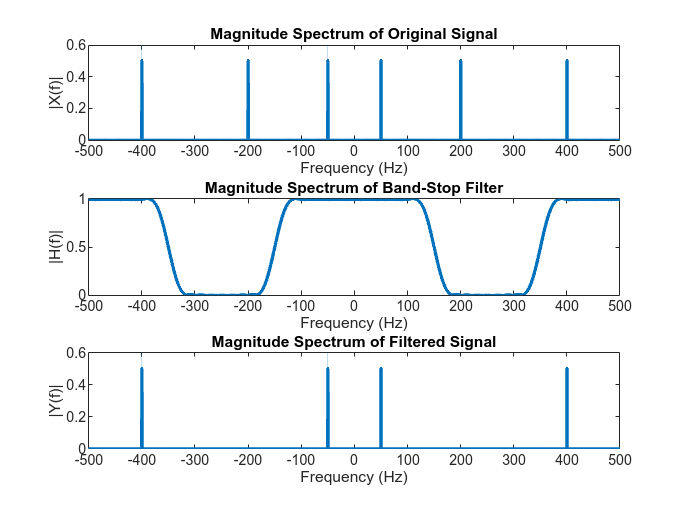

%task 5
clc; clear; close all;

fs= 1000;           
tmax= 3;              
dt= 1/fs;
t= dt:dt:tmax;
N= length(t);
f_low = 50;           
f_mid = 200;           
f_high= 400;          
x_low = sin(2*pi*f_low*t);
x_mid = sin(2*pi*f_mid*t);
x_high= sin(2*pi*f_high*t);
xt = x_low + x_mid + x_high;

Xs   = fft(xt, N);
X    = fftshift(Xs) / N;
freq = linspace(-fs/2, fs/2, N);

figure('Name','Band-Stop Filter (Task 5)','NumberTitle','off');
subplot(3,1,1);
plot(freq, abs(X), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');

f1 = 150;   
f2 = 350;  

L = 51;            
M = (L-1)/2;
n = 0:(L-1);

omega_f2   = 2*pi*f2/fs;
ImpLoWide  = sin(omega_f2*(n - M)) ./ (pi*(n - M));
ImpLoWide(M+1) = omega_f2 / pi;  

omega_f1   = 2*pi*f1/fs;
ImpLoNarrow = sin(omega_f1*(n - M)) ./ (pi*(n - M));
ImpLoNarrow(M+1) = omega_f1 / pi;
ImpBand = ImpLoWide - ImpLoNarrow;
ap = sin(pi*(n - M)) ./ (pi*(n - M));
ap(M+1) = 1; 
h_bs_ideal = ap - ImpBand;
% w[n] = 0.5 - 0.5*cos(2*pi*n/(L-1))
w = 0.5 - 0.5*cos(2*pi*n/(L-1));
h_bs = h_bs_ideal .* w;       

y = conv(xt, h_bs, 'same'); 
H    = fft(h_bs, N);
H    = fftshift(H);
Hmag = abs(H);

subplot(3,1,2);
plot(freq, Hmag, 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Spectrum of Band-Stop Filter');

Ys = fft(y, N);
Y  = fftshift(Ys) / N;

subplot(3,1,3);
plot(freq, abs(Y), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');

%post lab task 1
clc; clear; close all;

fs = 1000;          
tmax = 3;          
dt = 1/fs;
t = dt:dt:tmax;
N = length(t);

f1 = 100;   
f2 = 300;  
f3 = 450; 

x1 = sin(2*pi*f1*t);
x2 = sin(2*pi*f2*t);
x3 = sin(2*pi*f3*t);
xt = x1 + x2 + x3;

X = fftshift(fft(xt))/N;
freq = linspace(-fs/2, fs/2, N);

figure('Name','Post Lab Task 1: High-Pass Filter with Manual Hamming Window','NumberTitle','off');
subplot(3,1,1);
plot(freq, abs(X), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');
xlim([-fs/2 fs/2]);

fc = 250;          
L = 51;            
M = (L-1)/2;        
n = 0:(L-1);
omega_c = 2*pi*fc/fs;

h_lp = sin(omega_c*(n-M))./(pi*(n-M));
h_lp(M+1) = omega_c/pi; 

ap = sin(pi*(n-M))./(pi*(n-M));
ap(M+1) = 1;
h_hp_ideal = ap - h_lp;

w = 0.54 - 0.46*cos(2*pi*n/(L-1));

h_hp = h_hp_ideal .* w;

H = fftshift(fft(h_hp, N))/N;
subplot(3,1,2);
plot(freq, abs(H), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Spectrum of High-Pass Filter');
xlim([-fs/2 fs/2]);

y = conv(xt, h_hp, 'same');
Y = fftshift(fft(y, N))/N;
subplot(3,1,3);
plot(freq, abs(Y), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');
xlim([-fs/2 fs/2]);

%post lab task 2
clc; clear; close all;
fs = 1000;           
tmax = 3;            
dt = 1/fs;
t = dt:dt:tmax;
N = length(t);

f1 = 100;  
f2 = 250;   
f3 = 400;  

x1 = sin(2*pi*f1*t);
x2 = sin(2*pi*f2*t);
x3 = sin(2*pi*f3*t);
xt = x1 + x2 + x3;

X = fftshift(fft(xt))/N;
freq = linspace(-fs/2, fs/2, N);

figure('Name','Post Lab Task 2: Band-Reject Filter using Blackman Window','NumberTitle','off');
subplot(3,1,1);
plot(freq, abs(X), 'LineWidth',2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');
xlim([-fs/2 fs/2]);
ylim([0 1.2]);

L = 51;                
M = (L-1)/2;            
n = 0:(L-1);

f_low_stop  = 240;     
f_high_stop = 260;      
omega1 = 2*pi*f_low_stop/fs; 
omega2 = 2*pi*f_high_stop/fs; 

h_lp_wide = sin(omega2*(n - M)) ./ (pi*(n - M));
h_lp_wide(M+1) = omega2/pi;

h_lp_narrow = sin(omega1*(n - M)) ./ (pi*(n - M));
h_lp_narrow(M+1) = omega1/pi;

h_bp = h_lp_wide - h_lp_narrow;

ap = sin(pi*(n - M)) ./ (pi*(n - M));
ap(M+1) = 1;
h_bs_ideal = ap - h_bp;

w = 0.42 - 0.5*cos(2*pi*n/(L-1)) + 0.08*cos(4*pi*n/(L-1));

h_bs = h_bs_ideal .* w;
H = fftshift(fft(h_bs, N))/N;
subplot(3,1,2);
plot(freq, abs(H), 'LineWidth',2);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Spectrum of Band-Reject Filter');
xlim([-fs/2 fs/2]);

y = conv(xt, h_bs, 'same');
Y = fftshift(fft(y, N))/N;
subplot(3,1,3);
plot(freq, abs(Y), 'LineWidth',2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');
xlim([-fs/2 fs/2]);
ylim([0 1.2]);

%post lab task 3:
clc; clear; close all;
fs = 1000;          
fp = 100;           
fs_stop = 120;       
omega_p = 2*pi*fp/fs;      
omega_s = 2*pi*fs_stop/fs; 
delta_omega = omega_s - omega_p;  

As_values = [10, 40, 60];

figure('Name','Kaiser Window Low-Pass Filter Designs','NumberTitle','off');

for i = 1:length(As_values)
    As = As_values(i);
    L_est = (2*pi*(As - 7.95))/(14.36*delta_omega) + 1;
    L = ceil(L_est);
    if mod(L,2)==0, L = L + 1; end  
    if As < 21
        beta = 0;
    elseif As <= 50
        beta = 0.5842*(As-21)^0.4 + 0.07886*(As-21);
    else
        beta = 0.1102*(As-8.7);
    end
    
    M = (L-1)/2;            
    n = 0:(L-1);            
    omega_c = 2*pi*fp/fs;
    h_ideal = sin(omega_c*(n - M))./(pi*(n - M));
    h_ideal(M+1) = omega_c/pi;
    w = besseli(0, beta*sqrt(1 - ((n - M)/M).^2)) ./ besseli(0, beta);
    h = h_ideal .* w;
    [H, f_plot] = freqz(h, 1, 1024, fs);
    subplot(length(As_values),1,i);
    plot(f_plot, abs(H), 'LineWidth',1.5);
    xlabel('Frequency (Hz)');
    ylabel('|H(f)|');
    title(sprintf('Kaiser LP Filter: As = %d dB, L = %d, \\beta = %.2f', As, L, beta));
    grid on;
    xlim([0 fs/2]);
end
